# Pulse Sampling

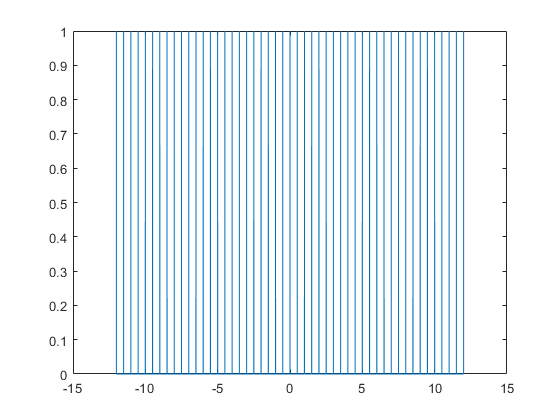

%%initialisation



% generate a pulse train
    f=2; %frequency of the impulse in Hz
    fs=f*200; % sample frequency is 10 times higher
    t=-12:1/fs:12; % time vector
    y=zeros(size(t));
    y(1:fs/f:end)=1;
    plot(t,y);

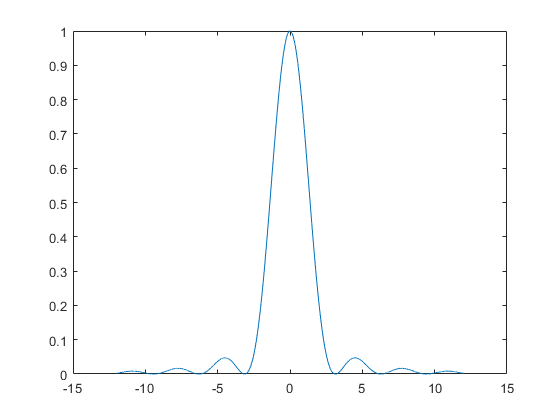

    
    x=(sinc(t/pi)).^2;
    plot(t,x)

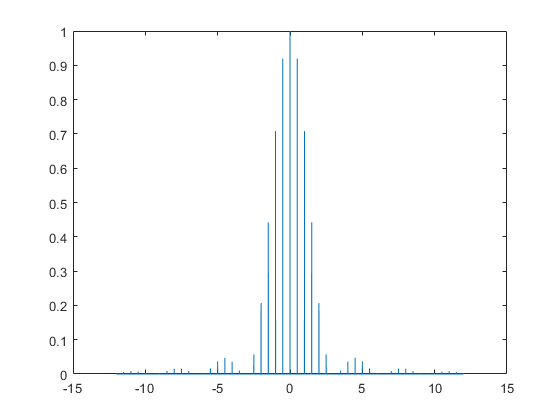

    y(1:fs/f:end)=x(1:fs/f:end);
    plot(t,y)

    
    N=size(t,2)

N = 9601

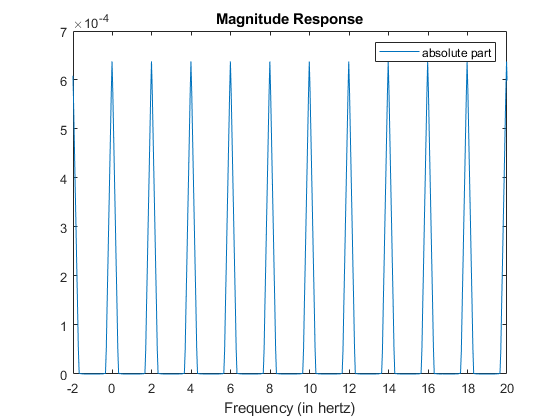

    Y = fftshift(fft(y));
   %%Frequency specifications:
   dF = fs/N;                      % hertz
   f = -fs/2:dF:fs/2-dF;           % hertz
   %%Plot the spectrum:
   figure;
   %plot(f,real(Y)/N,'DisplayName','real part');
   %hold on 
   %plot(f,imag(Y)/N,'DisplayName','imag part');
   plot(f,abs(Y)/N,'DisplayName','absolute part')
   legend
   
   xlabel('Frequency (in hertz)');
   title('Magnitude Response');
    xlim([-fs/200 fs/20])
   hold off